clear variables;
load("Parity Mixing/state_data.mat");
addpath("Wigner3j6j9j");

totalstate_num=length(state);
electron=Constant.ElementaryCharge;
c=Constant.LightSpeed;
a0=Constant.BohrRadius;
omega0=c/1036e-9*2*pi;
Es=6.5e6;

E0=2399169.688;
hbar=Constant.ReducedPlanck;

factor1=-electron^3*E0^2*Es*omega0/(8*sqrt(6)*c*hbar^2);
factor2=electron^3*E0^2*Es*omega0/(8*sqrt(3)*c*hbar^2);

### Term 1 $\mathcal{E}_{EQ1}$

sum_index=1;
for i=1:length(state)
    state2=state(i);
    for j=1:length(state)
        state1=state(j);
        omega1=state1.omega;
        omega2=state2.omega;

        term(1,sum_index)=(wigner_r(1,g_state,state2)-wigner_r(-1,g_state,state2))...
            *(wigner_r(1,state2,state1)-wigner_r(-1,state2,state1))...
            *(wigner_T(2,2,state1,g_state)-wigner_T(2,-2,state1,g_state))...
            /(omega2*(omega1-omega0));

        term(2,sum_index)=(wigner_r(1,g_state,state2)-wigner_r(-1,g_state,state2))...
            *(wigner_T(2,2,state2,state1)-wigner_T(2,-2,state2,state1))...
            *(wigner_r(1,state1,g_state)-wigner_r(-1,state1,g_state))...
            /(omega2*(omega1+omega0));

        term(3,sum_index)=(wigner_r(1,g_state,state2)-wigner_r(-1,g_state,state2))...
            *(wigner_r(1,state2,state1)-wigner_r(-1,state2,state1))...
            *(wigner_T(2,2,state1,g_state)-wigner_T(2,-2,state1,g_state))...
            /((omega2-omega0)*(omega1-omega0));

        term(4,sum_index)=(wigner_T(2,2,g_state,state2)-wigner_T(2,-2,g_state,state2))...
            *(wigner_r(1,state2,state1)-wigner_r(-1,state2,state1))...
            *(wigner_r(1,state1,g_state)-wigner_r(-1,state1,g_state))...
            /((omega2+omega0)*(omega1+omega0));

        term(5,sum_index)=(wigner_r(1,g_state,state2)-wigner_r(-1,g_state,state2))...
            *(wigner_T(2,2,state2,state1)-wigner_T(2,-2,state2,state1))...
            *(wigner_r(1,state1,g_state)-wigner_r(-1,state1,g_state))...
            /((omega2-omega0)*(omega1));

        term(6,sum_index)=(wigner_T(2,2,g_state,state2)-wigner_T(2,-2,g_state,state2))...
            *(wigner_r(1,state2,state1)-wigner_r(-1,state2,state1))...
            *(wigner_r(1,state1,g_state)-wigner_r(-1,state1,g_state))...
            /((omega2+omega0)*(omega1));

        term(7,sum_index)=(wigner_r(1,g_state,state2)-wigner_r(-1,g_state,state2))...
            *(wigner_T(2,-2,state2,state1)-wigner_T(2,2,state2,state1))...
            *(wigner_r(1,state1,g_state)-wigner_r(-1,state1,g_state))...
            /((omega2)*(omega1-omega0));
        
        term(8,sum_index)=(wigner_r(1,g_state,state2)-wigner_r(-1,g_state,state2))...
            *(wigner_r(1,state2,state1)-wigner_r(-1,state2,state1))...
            *(wigner_T(2,-2,state1,g_state)-wigner_T(2,2,state1,g_state))...
            /(omega2*(omega1+omega0));

        term(9,sum_index)=(wigner_T(2,-2,g_state,state2)-wigner_T(2,2,g_state,state2))...
            *(wigner_r(1,state2,state1)-wigner_r(-1,state2,state1))...
            *(wigner_r(1,state1,g_state)-wigner_r(-1,state1,g_state))...
            /((omega2-omega0)*(omega1-omega0));

        term(10,sum_index)=(wigner_r(1,g_state,state2)-wigner_r(-1,g_state,state2))...
            *(wigner_r(1,state2,state1)-wigner_r(-1,state2,state1))...
            *(wigner_T(2,-2,state1,g_state)-wigner_T(2,2,state1,g_state))...
            /((omega2+omega0)*(omega1+omega0));

        term(11,sum_index)=(wigner_T(2,-2,g_state,state2)-wigner_T(2,2,g_state,state2))...
            *(wigner_r(1,state2,state1)-wigner_r(-1,state2,state1))...
            *(wigner_r(1,state1,g_state)-wigner_r(-1,state1,g_state))...
            /((omega2-omega0)*(omega1));

        term(12,sum_index)=(wigner_r(1,g_state,state2)-wigner_r(-1,g_state,state2))...
            *(wigner_T(2,-2,state2,state1)-wigner_T(2,2,state2,state1))...
            *(wigner_r(1,state1,g_state)-wigner_r(-1,state1,g_state))...
            /((omega2+omega0)*(omega1));

        sum_index=sum_index+1;
    end
end


term_sum=factor1*sum(term,2);
term_sum_inEDM=term_sum/Es/electron*100;

total_sum_inEDM_EQ1=sum(term_sum_inEDM);
disp([num2str(total_sum_inEDM_EQ1),' e cm ']);

3.0059e-26 e cm 


### Term 2 $\mathcal{E}_{EQ2}$

sum_index=1;
for i=1:length(state)
    state2=state(i);
    for j=1:length(state)
        state1=state(j);
        omega1=state1.omega;
        omega2=state2.omega;

        term(1,sum_index)=(wigner_r(1,g_state,state2)-wigner_r(-1,g_state,state2))...
            *(wigner_r(0,state2,state1))...
            *(wigner_T(2,1,state1,g_state)+wigner_T(2,-1,state1,g_state))...
            /(omega2*(omega1-omega0));

        term(2,sum_index)=(wigner_r(1,g_state,state2)-wigner_r(-1,g_state,state2))...
            *(wigner_T(2,1,state2,state1)+wigner_T(2,-1,state2,state1))...
            *(wigner_r(0,state1,g_state))...
            /(omega2*(omega1+omega0));

        term(3,sum_index)=(wigner_r(0,g_state,state2))...
            *(wigner_r(1,state2,state1)-wigner_r(-1,state2,state1))...
            *(wigner_T(2,1,state1,g_state)+wigner_T(2,-1,state1,g_state))...
            /((omega2-omega0)*(omega1-omega0));

        term(4,sum_index)=(-wigner_T(2,1,g_state,state2)-wigner_T(2,-1,g_state,state2))...
            *(wigner_r(1,state2,state1)-wigner_r(-1,state2,state1))...
            *(wigner_r(0,state1,g_state))...
            /((omega2+omega0)*(omega1+omega0));

        term(5,sum_index)=(wigner_r(0,g_state,state2))...
            *(wigner_T(2,1,state2,state1)+wigner_T(2,-1,state2,state1))...
            *(wigner_r(1,state1,g_state)-wigner_r(-1,state1,g_state))...
            /((omega2-omega0)*(omega1));

        term(6,sum_index)=(wigner_T(2,1,g_state,state2)+wigner_T(2,-1,g_state,state2))...
            *(wigner_r(0,state2,state1))...
            *(wigner_r(1,state1,g_state)-wigner_r(-1,state1,g_state))...
            /((omega2+omega0)*(omega1));

        term(7,sum_index)=(wigner_r(1,g_state,state2)-wigner_r(-1,g_state,state2))...
            *(-wigner_T(2,-1,state2,state1)-wigner_T(2,1,state2,state1))...
            *(wigner_r(0,state1,g_state))...
            /((omega2)*(omega1-omega0));
        
        term(8,sum_index)=(wigner_r(1,g_state,state2)-wigner_r(-1,g_state,state2))...
            *(wigner_r(0,state2,state1))...
            *(-wigner_T(2,-1,state1,g_state)-wigner_T(2,1,state1,g_state))...
            /(omega2*(omega1+omega0));

        term(9,sum_index)=(-wigner_T(2,-1,g_state,state2)-wigner_T(2,1,g_state,state2))...
            *(wigner_r(1,state2,state1)-wigner_r(-1,state2,state1))...
            *(wigner_r(0,state1,g_state))...
            /((omega2-omega0)*(omega1-omega0));

        term(10,sum_index)=(wigner_r(0,g_state,state2))...
            *(wigner_r(1,state2,state1)-wigner_r(-1,state2,state1))...
            *(-wigner_T(2,-1,state1,g_state)-wigner_T(2,1,state1,g_state))...
            /((omega2+omega0)*(omega1+omega0));

        term(11,sum_index)=(-wigner_T(2,-1,g_state,state2)-wigner_T(2,1,g_state,state2))...
            *(wigner_r(0,state2,state1))...
            *(wigner_r(1,state1,g_state)-wigner_r(-1,state1,g_state))...
            /((omega2-omega0)*(omega1));

        term(12,sum_index)=(wigner_r(0,g_state,state2))...
            *(-wigner_T(2,-1,state2,state1)-wigner_T(2,1,state2,state1))...
            *(wigner_r(1,state1,g_state)-wigner_r(-1,state1,g_state))...
            /((omega2+omega0)*(omega1));

        sum_index=sum_index+1;
    end
end


term_sum=factor2*sum(term,2);
term_sum_inEDM=term_sum/Es/electron*100;

total_sum_inEDM_EQ2=sum(term_sum_inEDM);
disp([num2str(total_sum_inEDM_EQ2),' e cm ']);

-8.5732e-27 e cm 


### Summary

EDM_oscillation_amp=(total_sum_inEDM_EQ1+total_sum_inEDM_EQ2)/2;
disp([num2str(EDM_oscillation_amp),' e cm ']);

1.0743e-26 e cm 


function result=radial_T(state1,state0)

    % 399-556
if state1.note=="399" && state0.note=="556"
    result=-4.535*(Constant.BohrRadius)^2;
elseif state0.note=="399" && state1.note=="556"
    result=-4.535*(Constant.BohrRadius)^2;

    % 556-556
elseif state1.note=="556" && state0.note=="556"
    result=7.949*(Constant.BohrRadius)^2;

    % g-361
elseif state1.note=="g" && state0.note=="361"
    result=-6.963*(Constant.BohrRadius)^2;
elseif state0.note=="g" && state1.note=="361"
    result=-6.963*(Constant.BohrRadius)^2;

    % g-404
elseif state1.note=="g" && state0.note=="404"
    result=3.248*(Constant.BohrRadius)^2;
elseif state0.note=="g" && state1.note=="404"
    result=3.248*(Constant.BohrRadius)^2;
    
    % 399-399
elseif state1.note=="399" && state0.note=="399"
    result=-8*(Constant.BohrRadius)^2;


else
    result=0;
end

end

function result=radial_r(state1,state0)
% Right low & Left high : positive

    % g-399
if state1.note=="g" && state0.note=="399"
    result=4.15*Constant.BohrRadius;
elseif state0.note=="g" && state1.note=="399"
    result=-4.15*Constant.BohrRadius;

    % g-556
elseif state1.note=="g" && state0.note=="556"
    result=0.54*Constant.BohrRadius;
elseif state0.note=="g" && state1.note=="556"
    result=-0.54*Constant.BohrRadius;

    % 556-361
elseif state1.note=="556" && state0.note=="361"
    result=1.57*Constant.BohrRadius;
elseif state0.note=="556" && state1.note=="361"
    result=-1.57*Constant.BohrRadius;

    % 556-404
elseif state1.note=="556" && state0.note=="404"
    result=4*Constant.BohrRadius;
elseif state0.note=="556" && state1.note=="404"
    result=-4*Constant.BohrRadius;



else
    result=0;
end
end



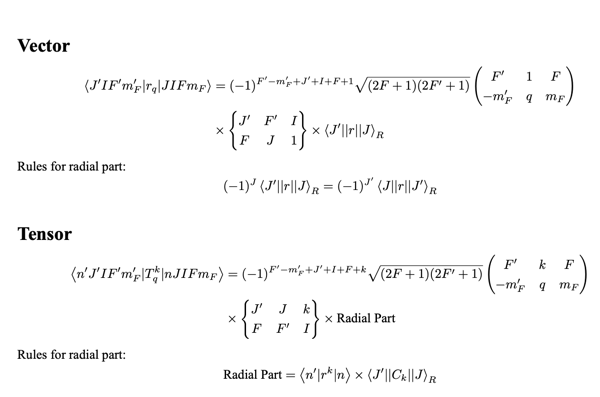

function result=wigner_T(k,q,state1,state0)
F1=state1.F;
F0=state0.F;
J1=state1.J;
J0=state0.J;
mf1=state1.mf;
mf0=state0.mf;
I0=state0.I;
result=(-1)^(F1-mf1+J1+I0+F0+k)*sqrt((2*F0+1)*(2*F1+1))*Wigner3j(F1,k,F0,-mf1,q,mf0)...
    *Wigner6j(J1,J0,k,F0,F1,I0)*radial_T(state1,state0);
end
function result=wigner_r(q,state1,state0)
F1=state1.F;F0=state0.F;
J1=state1.J;J0=state0.J;
mf1=state1.mf;mf0=state0.mf;
I0=state0.I;
result=(-1)^(F1-mf1+J1+I0+F0+1)*sqrt((2*F0+1)*(2*F1+1))*Wigner3j(F1,1,F0,-mf1,q,mf0)...
    *Wigner6j(J1,F1,I0,F0,J0,1)*radial_r(state1,state0);
end